tim_freq = 40000000;
samplerate = 100;
graph_resolution_s = 5;

% Load the data
data = dlmread('./data/esp32ap_10ms_24hr.txt');
tim_timestamps_arr = data(:,1) - data(2,1);
tsf_timestamps_arr   = data(:,2) - data(2,2);

% Compute linear fit and predicted values
p = polyfit(tim_timestamps_arr, tsf_timestamps_arr, 1);

tsf_predicted = polyval(p, tim_timestamps_arr);

% Compute error: predicted minus real values
error_vals = tsf_predicted - tsf_timestamps_arr;

% Downsample error data to ~1000 points by selecting the peak (largest absolute error)
num_points = ceil(length(tim_timestamps_arr)/samplerate);
N = length(error_vals);
segment_length = floor(N / num_points);

reduced_error = zeros(num_points,1);
reduced_time  = zeros(num_points,1);

for i = 1:num_points
    % Define the index range for this segment
    idx_start = (i-1)*segment_length + 1;
    if i < num_points
       idx_end = i*segment_length;
    else
       idx_end = N;  % include any leftover points in the final segment
    end
    segment = error_vals(idx_start:idx_end);
    
    % Find the index of the peak absolute error in the segment
    [~, local_max_idx] = max(abs(segment));
    
    % Save the corresponding error and time value
    reduced_error(i) = segment(local_max_idx);
    reduced_time(i) = tim_timestamps_arr(idx_start + local_max_idx - 1);
end

reduced_time = reduced_time / tim_freq

reduced_time = 1.0e+04 *

    0.0001
    0.0001
    0.0002
    0.0003
    0.0005
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009


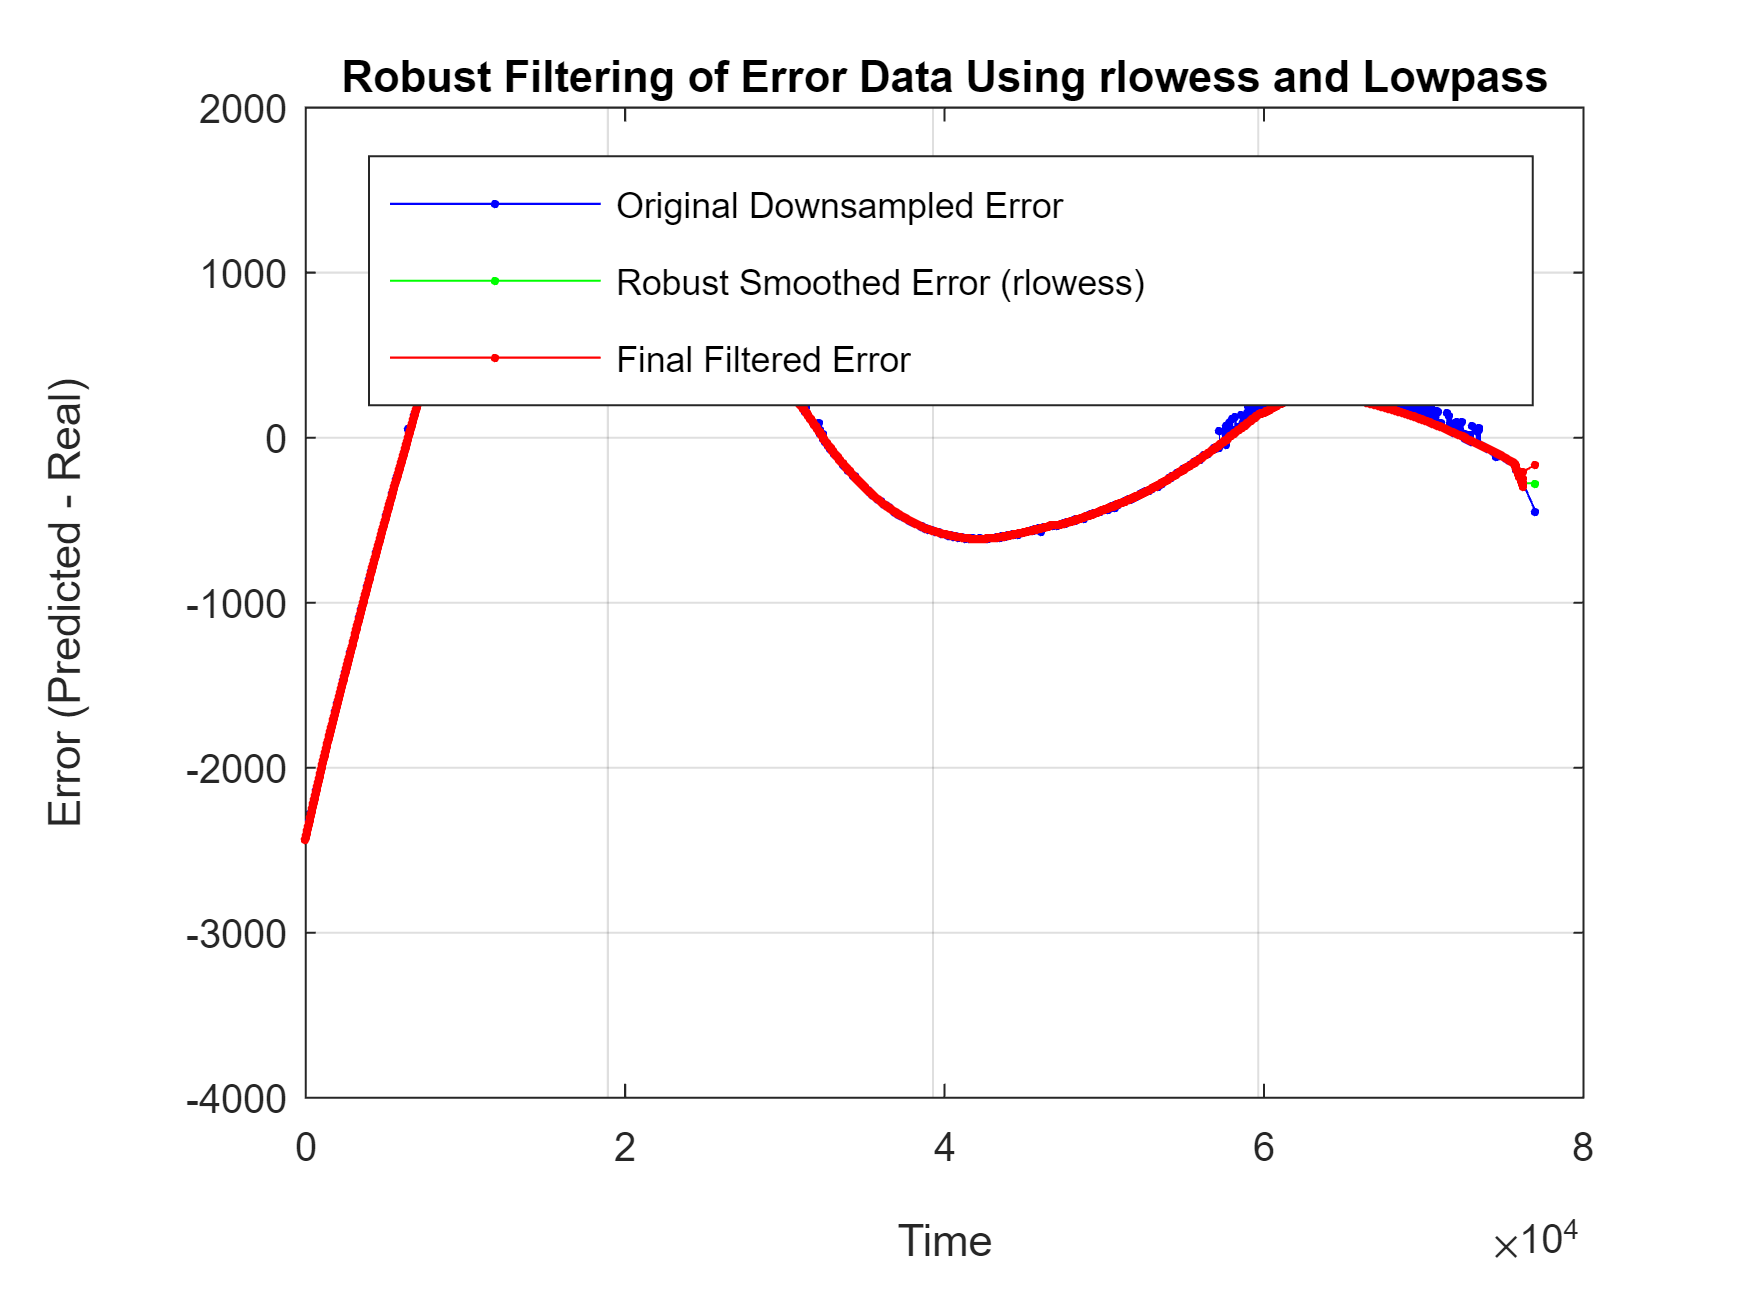


% Estimate the sampling frequency from the reduced time array.
sampleInterval = mean(diff(reduced_time));   % average time step (assumes time in seconds)
fs = 1 / sampleInterval;                      % sampling frequency

% Choose a cutoff frequency (adjust as needed)
cutoffFreq = fs / 20;

% --- Robust Filtering Section ---
% Use a robust smoothing method with smoothdata. 'rlowess' applies robust locally weighted regression.
windowSize = 51;  % Adjust the window size based on your data characteristics
robust_smoothed_error = smoothdata(reduced_error, 'rlowess', windowSize);

% Optionally, apply a lowpass filter on the robust-smoothed data for further smoothing.
final_filtered_error = lowpass(robust_smoothed_error, cutoffFreq, fs);

% --- Plotting Section ---
figure;
plot(reduced_time, reduced_error, 'b.-', 'DisplayName', 'Original Downsampled Error');
hold on;
plot(reduced_time, robust_smoothed_error, 'g.-', 'DisplayName', 'Robust Smoothed Error (rlowess)');
plot(reduced_time, final_filtered_error, 'r.-', 'DisplayName', 'Final Filtered Error');
xlabel('Time');
ylabel('Error (Predicted - Real)');
title('Robust Filtering of Error Data Using rlowess and Lowpass');
legend();
grid on;